### Description: Code to calculate  FFT of a stationary signal with leakage

### Author: Vishu Sharma

### Last Modified: 09.11.2021

clear all, clc

Fs = .4; % Sampling frequency
T = 1/Fs; % Sampling period
L = 128; % length of signal
t = (0: L-1)*T;
r=2*pi;

## Signal and Noise

A = 100*cos(.04*r*t);
B = 205*cos(.07*r*t);
N = 0*rand(size(t));

x = A + B+ N;

## Signal in time domain

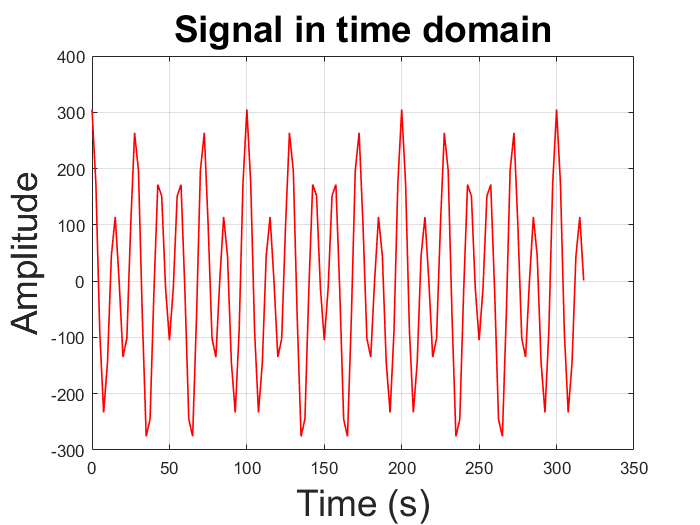

plot(t,x, 'r','LineWidth',1)
grid on
title('Signal in time domain', 'FontSize', 22)
xlabel('Time (s)', 'FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

## Fourier Spectral Analysis

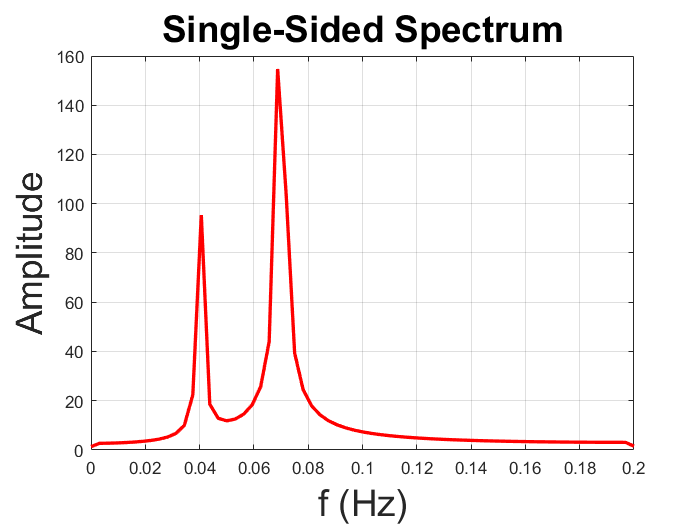

n = 2^nextpow2(L);         % num of points for FFT

Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'r','LineWidth',2) 

title('Single-Sided Spectrum','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on